# Accessing Objects using the Hierarchy

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

avgEventsPerDecade = [  74.2 83.8 99.2 159;
                        29 34 31.2 45];
grps = ["All Events" "US Events"];
labs = ["1800s" "First half of 1900s" "Second half of 1900s" "2000s"];
numEvents = [89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152; 19];
avgEventsPerDecade

avgEventsPerDecade =    74.2000   83.8000   99.2000  159.0000
   29.0000   34.0000   31.2000   45.0000


b = bar(avgEventsPerDecade) 

b =   1×4 Bar array:

    Bar    Bar    Bar    Bar


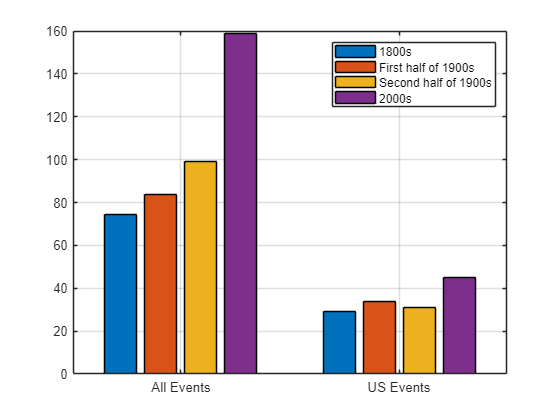

legend(labs)
xticklabels(grps)
grid on

## Task 1

You can use the `gcf` command to grab the current figure, similar to the `gca` function.

f = gcf

f =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


## Task 2

The goal of this practice is to find and modify graphics objects by using the graphics hierarchy.

Since axes is a *child* of the figure, you can use the `Children` property of the figure object `f` to get the axes object.

theBabies = f.Children

theBabies =   2×1 graphics array:

  Legend    (1800s, First half of 1900s, Second half of 1900s, 2000s)
  Axes


## Task 3

You can extract elements from a graphics array with parentheses, just like other arrays.

`graphicsArray``(``5``)`

ax = theBabies(2)

ax =   Axes with properties:

             XLim: [0.5091 2.4909]
             YLim: [0 160]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


## Task 4

The default color of both of the axes and the figure objects is white, represented by `[1 1 1]` in the `Color` property of each.

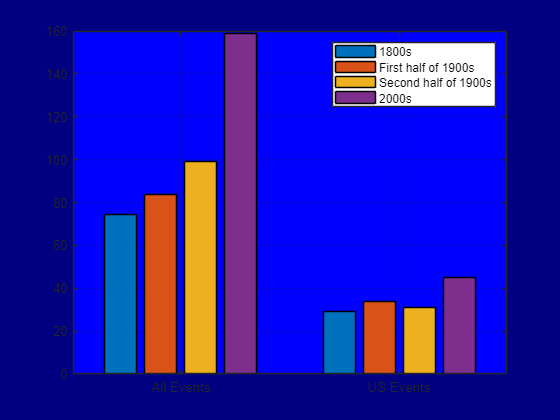

f.Color = [0 0 .5];
ax.Color = [0 0 1];

## Task 5

Recall that you can access properties of the individual axes objects.

`ax.XAxis.propertyName`

ax.XAxis.Color = [1 1 0]

ax =   Axes with properties:

             XLim: [0.5091 2.4909]
             YLim: [0 160]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


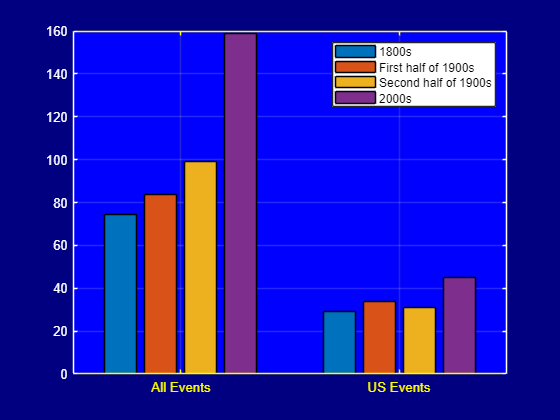

ax =   Axes with properties:

             XLim: [0.5091 2.4909]
             YLim: [0 160]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.Color = [1 1 1]

## Task 6

The legend is a graphics object that is also a *child* of the figure. You can get a handle to this legend by either assigning the output of the `legend` function to a variable or as a child of the figure.

In this example, the legend is the first element of the graphics array, `theBabies`, which contains the children of the current figure.

lgd = theBabies(1)

lgd =   Legend (1800s, First half of 1900s, Second half of 1900s, 2000s) with properties:

         String: {'1800s'  'First half of 1900s'  'Second half of 1900s'  '2000s'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5899 0.7544 0.2964 0.1464]
          Units: 'normalized'

  Show all properties


lgd.FontWeight = "Bold"

lgd =   Legend (1800s, First half of 1900s, Second half of 1900s, 2000s) with properties:

         String: {'1800s'  'First half of 1900s'  'Second half of 1900s'  '2000s'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5827 0.7544 0.3036 0.1464]
          Units: 'normalized'

  Show all properties


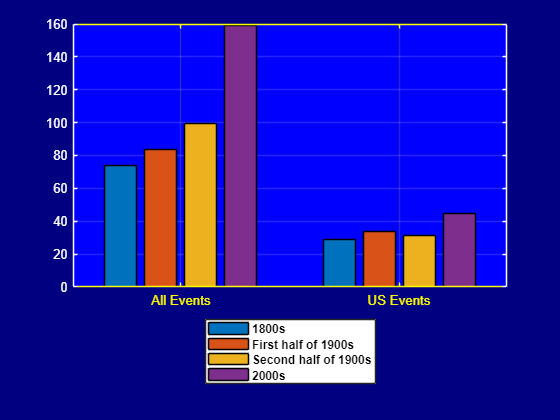

lgd =   Legend (1800s, First half of 1900s, Second half of 1900s, 2000s) with properties:

         String: {'1800s'  'First half of 1900s'  'Second half of 1900s'  '2000s'}
       Location: 'southoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.3661 0.0869 0.3036 0.1464]
          Units: 'normalized'

  Show all properties


lgd.Location = "southoutside"